# 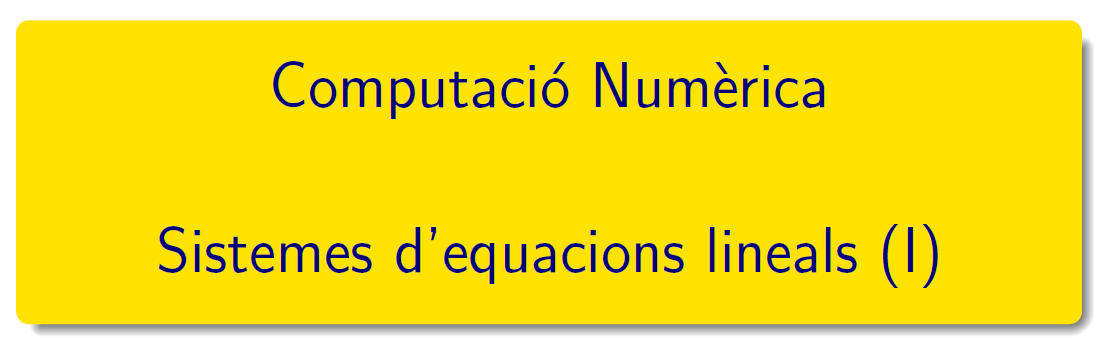

===============================================================================

# Pràctica 2  - Activitat 3: àlgebra lineal numèrica

### Aprenem ... 

### 2.1 Normes de vectors

v =(1:3)'             % vector columna de matlab

v =      1
     2
     3


w=[1,-1,0]

w =      1    -1     0


w*v           % producte escalar = (fila x columna)

ans =     -1


v*w            % producte matricial = (columna x fila)

ans =      1    -1     0
     2    -2     0
     3    -3     0


v.*v

ans =      1
     4
     9


v = rand(1,5)            % un vector qualsevol

v =       0.26221      0.60284      0.71122      0.22175      0.11742


v = -5 + (5+5)*rand(10,1)

v =       -2.0332
      -1.8122
     -0.75833
     0.078583
      -4.1448
      -2.3752
       3.0101
      -4.7078
       4.2885
       2.3033


%    abs(r)          % componentes del vector sin signo
n1 = norm(v,1), sum(abs(v))         % norma 1    

n1 =        25.512


ans =        25.512


n2 = norm(v),sqrt(sum((v).^2))      % norma 2    

n2 =        9.2597


ans =        9.2597


n3 = norm(v,'inf'), max(abs(v))     %norma del màxim

n3 =        4.7078


ans =        4.7078


### 2.2 Normes de matrius

Moltes matrius per exemples:  ones, eye, zero, rand, randn, magic, wilkinson, hilb, invhilb, hadamard, compan, hankel, toeplitz, gallery.

A = tril(-5 + (5+5)*rand(4,3)) % Matrius per exemples 

A =      -0.11391            0            0
      0.78525      0.46806            0
      -2.6272      0.21136       1.7914
     -0.41151      -2.6841      -1.0448


% norm(A,1),sum(abs(A))                      % norma 1
norm(A), sqrt(eig(A'*A)) 

ans =        3.3199


ans =       0.21233
       2.8987
       3.3199


A'*A% norma 2

ans =        7.7009      0.91679      -4.2762
      0.91679       7.4679        3.183
      -4.2762        3.183       4.3007


% norm(A,'inf'), sum(abs(A),2)               % norma infinit               
% Matrius per exemples 
% norm(A,1),sum(A)                      % norma 1
% norm(A), sqrt(eig(A'*A))              % norma 2
% norm(A,'inf'), sum(A,2)               % norma infinit        

### Practiquem ...

#### Exercici 1.  Normes vectorials i matricials predefinits en MATLAB®

Exercici 2, pàgina 39 apunts

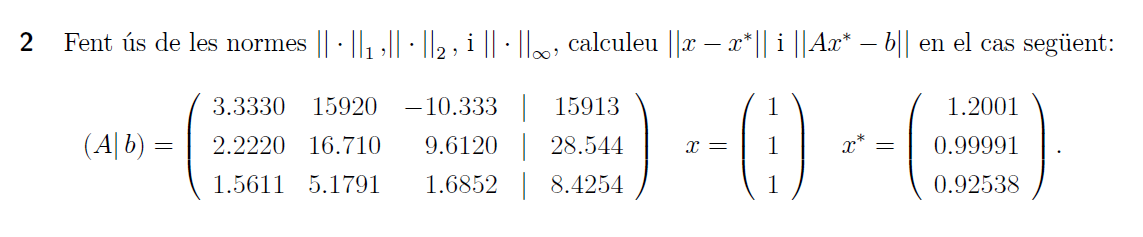

format shortG
A = [3.3330 15920 -10.333 15913; 2.2220 16.710 9.6120  28.544; 1.5611 5.1791 1.6852  8.4254] ;     
b = A(:,4),   A(:,4)= []

b =         15913
       28.544
       8.4254


A =         3.333        15920      -10.333
        2.222        16.71        9.612
       1.5611       5.1791       1.6852


x = ones(size((b))), y=[1.2001; 0.99991;0.92538]

x =      1
     1
     1


y =        1.2001
      0.99991
      0.92538


% Norma 1
Dx = norm(x-y, 1), ry = norm(b - A*y, 1), rx = norm(b - A*x,1)

Dx =       0.27481


ry =       0.46547


rx =    3.5527e-15


% Norma 2
Dx = norm(x-y), ry = norm(b-A*y), rx = norm(b-A*x)

Dx =       0.21356


ry =       0.33141


rx =    3.5527e-15


% Norma infinit
Dx = norm(x-y,'inf'), ry = norm(b-A*y,'inf'), rx = norm(b-A*x,'inf')

Dx =        0.2001


ry =       0.27413


rx =    3.5527e-15


### 2.3 Tipus de matrius

[Matrius de Matlab](https://es.mathworks.com/help/matlab/math/matrices-in-the-matlab-environment.html) (resum de com treballar amb matrius) 

Biblioteca de [matrius en Matlab](https://es.mathworks.com/help/matlab/constants-and-test-matrices.html?lang=en), i més matrius en Matlab [gallery](https://es.mathworks.com/help/matlab/ref/gallery.html)

hilb(4)

ans =             1          0.5      0.33333         0.25
          0.5      0.33333         0.25          0.2
      0.33333         0.25          0.2      0.16667
         0.25          0.2      0.16667      0.14286


### Practiquem ...

#### Exercici 2.  Matrius i vectors predefinits en MATLAB®

Definiu la matriu  $A=\left(a_{ij}\right)_{51\times 51}$ i el vector  $b=(b_{i})_{51\times 1}$   

- Amb zeros a  totes les seves components

A = zeros(5)

A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


- Amb uns a les seves components

A = ones(5)

A =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


- Amb nombres al·leatòris uniformes de l'interval [-2,2]

a = -2; b = 2;
A = a + (b-a)*rand(5)

A =     -0.080311        1.222      -1.8853    0.0018865      -1.7142
       1.6189      0.30689    -0.040394     -0.11565     0.086599
      0.43947      -1.2683      -1.3283      -1.7615      -1.6131
      0.47067      -1.0403       1.9147      0.72789       1.2726
       1.4378        1.546      0.85078      -1.8303       1.2702


- Amb nombres al·leatòris normals amb $\mu = 0$ i $\sigma = 1$

A = randn(5) 

A =       0.85773      0.53616      -2.1237      0.82573      0.30182
     -0.69116      0.89789     -0.50459      -1.0149      0.39993
      0.44938     -0.13194      -1.2706     -0.47107     -0.92996
      0.10063      -0.1472     -0.38258      0.13702     -0.17683
      0.82607       1.0078      0.64868     -0.29186      -2.1321


#### Exercici 3.  Matriu triangular superior

Definiu la matriu  $U=\left(u_{ij}\right)_{15\times 15}$ i el vector  $b=(b_{i})_{15\times 1}$ com  $u_{ij}=\left\{\begin{array}{rr} \cos (ij) & i\leq j\,,\\ & \\ 0 & i>j\,, \end{array}\right.
	\qquad\mbox{i}\qquad b_{i}=\frac1{1+i^2}\,. $

clearvars;
n = 15;
u = zeros(n);
for i = 1:n
    for j=i:n
        u(i,j) = cos(i*j);
    end
    b(i,1) = 1/(1+i^2);
end
TS = u(1:5,1:5), v=b(1:5,1)

TS =        0.5403     -0.41615     -0.98999     -0.65364      0.28366      0.96017       0.7539      -0.1455     -0.91113     -0.83907
            0     -0.65364      0.96017      -0.1455     -0.83907      0.84385      0.13674     -0.95766      0.66032      0.40808
            0            0     -0.91113      0.84385     -0.75969      0.66032     -0.54773      0.42418     -0.29214      0.15425
            0            0            0     -0.95766      0.40808      0.42418     -0.96261      0.83422     -0.12796     -0.66694
            0            0            0            0       0.9912      0.15425     -0.90369     -0.66694      0.52532      0.96497
            0            0            0            0            0     -0.12796     -0.39999     -0.64014     -0.82931     -0.95241
            0            0            0            0            0            0      0.30059      0.85322       0.9859      0.63332
            0            0            0            0            0            0

v =           0.5
          0.2
          0.1
     0.058824
     0.038462


#### Exercici 4.  Matriu triangular inferior

Definiu la matriu  $L=\left(l_{ij}\right)_{20\times 20}$ i el vector  $b=(b_{i})_{20\times 1}$ com  $l_{ij}=\left\{\begin{array}{rr} \sqrt{ij}  & i\geq j\,,\\ & \\ 0 & i<j\,, \end{array}\right.
	\qquad\mbox{i}\qquad b_{i}=2^{8-i}\,. $

clearvars;
n = 20; 
l = zeros(n);
for i = 1:n
    for j=1:i
        l(i,j) = cos(i*j);
    end
    b(i,1) = 2^(8-i);
end
TI = l(1:5,1:5), v = b(1:5,1)

TI =        0.5403            0            0            0            0
     -0.41615     -0.65364            0            0            0
     -0.98999      0.96017     -0.91113            0            0
     -0.65364      -0.1455      0.84385     -0.95766            0
      0.28366     -0.83907     -0.75969      0.40808       0.9912


v =    128
    64
    32
    16
     8


#### Exercici 5.  Matriu quadrada 

Definiu la matriu  $A=\left(a_{ij}\right)_{51\times 51}$ i el vector  $b=(b_{i})_{51\times 1}$ com  $a_{ij}=\left\{\begin{array}{rl} (-1)^{i} &\ i=j\,,\\ & \\ 2 &\ 1\le|i-j|\le 2\,, \end{array}\right.
	\qquad\mbox{i}\qquad b_{i}=i\,.$

clearvars;
n = 51; 
a = 2*ones(n);
for i=1:n
    a(i,i) = (-1)^i;
    b(i,1) = i;
end
a = a - triu(a,3);
a = a - tril(a,-3);
A = a(1:5,1:5), v = b(1:5,1)   

A =     -1     2     2     0     0
     2     1     2     2     0
     2     2    -1     2     2
     0     2     2     1     2
     0     0     2     2    -1


v =      1
     2
     3
     4
     5


#### Exercici 6. Tranformacions ortogonals

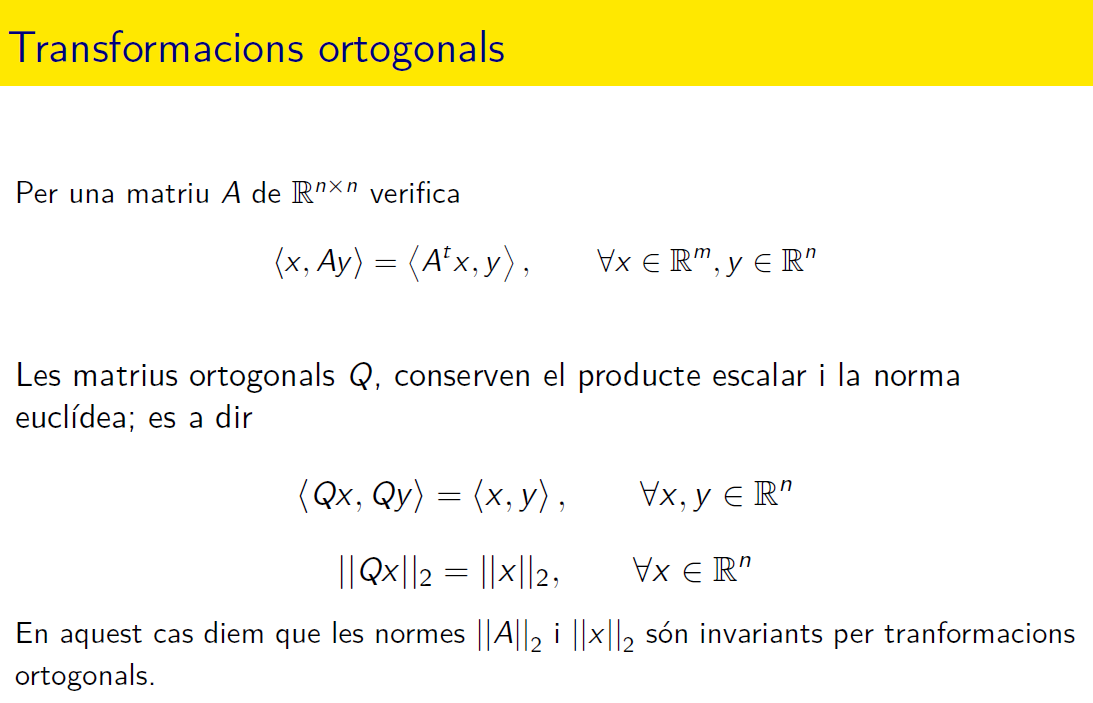

a) Verifica la propietat <x,Ay> = <A^tx,y> per a qualsevol matriu A quadrada.

format shortG
A = gallery('lehmer',5)     % Una matriu de la biblioteca

A =             1          0.5      0.33333         0.25          0.2
          0.5            1      0.66667          0.5          0.4
      0.33333      0.66667            1         0.75          0.6
         0.25          0.5         0.75            1          0.8
          0.2          0.4          0.6          0.8            1


x = ones(5,1); y = diag(hilb(5));   [x,y]  % dos vectors columna

ans =             1            1
            1      0.33333
            1          0.2
            1      0.14286
            1      0.11111


b) Verifica la propietat <Qx,Qy> = <x,y> per a qualsevol matriu Q ortogonal.

Q = gallery('orthog',6)    % Una matriu ortogonal de la biblioteca

Q =       0.23192      0.41791      0.52112      0.52112      0.41791      0.23192
      0.41791      0.52112      0.23192     -0.23192     -0.52112     -0.41791
      0.52112      0.23192     -0.41791     -0.41791      0.23192      0.52112
      0.52112     -0.23192     -0.41791      0.41791      0.23192     -0.52112
      0.41791     -0.52112      0.23192      0.23192     -0.52112      0.41791
      0.23192     -0.41791      0.52112     -0.52112      0.41791     -0.23192


x = ones(6,1); y = diag(hilb(6)); [x,y]      % dos vectors columna

ans =             1            1
            1      0.33333
            1          0.2
            1      0.14286
            1      0.11111
            1     0.090909


### 2.4 Resolució de sistemas d'equacions lineals 

### Aprenem ...

#### Exercici 7: funcions de  MATLAB®

Calculeu  el determinant, la transposta, la inversa, els valors propis i els vectors propis de la matriu A definida per

$\displaystyle A=\left(\begin{array}{rrr} 1 & 2 & 1\\ -2 & 7 & 3\\ 1 &-1 &10 \end{array}\right)$    )Exercici 1, pàgina 41)

A = [1 2 1; -2 7 3; 1 -1 10]

A =      1     2     1
    -2     7     3
     1    -1    10


determinant = det(A)   % determinant

determinant =    114


transpodada = A'       % transposta

transpodada =      1    -2     1
     2     7    -1
     1     3    10


inversa = inv(A)   % inversa

inversa =       0.64035     -0.18421   -0.0087719
      0.20175     0.078947     -0.04386
     -0.04386     0.026316     0.096491


[V,L] = eig(A)

V =       0.91903     -0.34633      0.24387
      0.38888     -0.92036      0.67345
    -0.064465     -0.18162      0.69785


L =        1.7761            0            0
            0       6.8394            0
            0            0       9.3844


#### Exercici 8. **Propagació de l'error. Sistema lineal mal condicionat.**

. Resoleu el sistema $\left\{\begin{array}{rcrcr}2x&-&4y&=&1 \\ -2.998x&+&6.001y&=&2 \\\end{array}\right.$   fent ús de la instrucció [linsolve](https://es.mathworks.com/help/matlab/ref/linsolve.html) de  MATLAB®

Compareu la solució  amb la del sistema  $\left\{\begin{array}{rcrcr}2x&-&4y&=&1 \\ -2.998x&+&6y&=&2 \\\end{array}\right.$. Com són les dues solucions? 

És un problema estable?    (Exercici1, pàgina 39)

Calculeu el nombre de condició de la matriu associada al sistema lineal.  

clearvars;
format shortG
b=[1, 2]; 
%%
B1=[2 -4; -2.998 6.001],x=linsolve(B1,b')

B1 =             2           -4
       -2.998        6.001


x =        1400.1
        699.8


%%
B2=[2 -4; -3 6.001], x=linsolve(B2,b')

B2 =             2           -4
           -3        6.001


x =        7000.5
         3500


fprintf('El nombre de condició de la matriu B1 és %g\n',cond(B1))

El nombre de condició de la matriu B1 és 6500


fprintf('El nombre de condició de la matriu B2 és %g\n',cond(B2))

El nombre de condició de la matriu B2 és 32506


#### Nombre de condició d'una matriu

Càlcul del nombre de condició d'una matriu en Matlab®: consulteu [condition number of matrix](https://es.mathworks.com/help/symbolic/cond.html)

format shortG
H = hilb(4);
condN2 = cond(H), condN1 = cond(H,1), condNf = cond(H,'fro'), condNi = cond(H,inf)

condN2 =         15514


condN1 =         28375


condNf =         15614


condNi =         28375


### **Practiquem ... **

**Vector residu i nombre de condició**

- `Exercici 9.` Estudiem com varia la solució del sistema lineal quan modifiquem només el terme independent $A(x+\delta x) = b+\delta b$


$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8 & 7 & 32.1\\
7 & 5 & 6 & 5 & 22.9\\
8 & 6 & 10 & 9 & 33.1\\
7 & 5 & 9 & 10 & 30.9\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


format shortG
A=[10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10]

A =     10     7     8     7
     7     5     6     5
     8     6    10     9
     7     5     9    10


% Sistema lineal 
b1=[32; 23; 33; 31];
b2=[32.1; 22.9; 33.1; 30.9];
B=[b1,b2], x=A\B

B =            32         32.1
           23         22.9
           33         33.1
           31         30.9


x =             1          9.2
            1        -12.6
            1          4.5
            1         -1.1


fprintf('paràmetres de condicionament\n'),K=cond(A,1), RK=rcond(A)

paràmetres de condicionament


K =          4488


RK =    0.00022282


fprintf('pertorbació en el vector b: db\n'), db = norm(b1-b2,'inf')/norm(b1,'inf')

pertorbació en el vector b: db


db =     0.0030303


fprintf('pertorbació en el vector x: dx\n'),dx = norm(x(:,1)-x(:,2),'inf')/norm(x(:,1),'inf')

pertorbació en el vector x: dx


dx =          13.6


fprintf('Error amplificat fp :\n'), fp = dx/db

Error amplificat fp :


fp =          4488


- `Exercici 10.` Estudieu com varia la solució del sistema lineal quan modifiquem només la matriu del sistema $(A+\Delta)(x+\delta x) = b$ 


$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8.01& 7.02 & 32\\
7.08 & 5.04 & 6 & 5 & 23\\
8 & 5.98 & 9.89 & 9 & 33\\
6.99 & 4.99 & 9 & 9.98& 31\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


A=[10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10]

A =     10     7     8     7
     7     5     6     5
     8     6    10     9
     7     5     9    10


A2=[10 7 8.01 7.02; 7.08 5.04 6 5; 8 5.98 9.89 9; 6.99 4.99 9 9.98]

A2 =            10            7         8.01         7.02
         7.08         5.04            6            5
            8         5.98         9.89            9
         6.99         4.99            9         9.98


% Sistema lineal 
b1=[32; 23; 33; 31];
b2=[32.1; 22.9; 33.1; 30.9];
x = A\b1, x2 = A\b2

x =      1
     1
     1
     1


x2 =           9.2
        -12.6
          4.5
         -1.1


fprintf('paràmetres de condicionament\n'),KA=cond(A,1), KA2=cond(A2,1)

paràmetres de condicionament


KA =          4488


KA2 =         21020


fprintf('pertorbació en la matriu A: dA\n'), dA = norm(A-A2,'inf')/norm(A,'inf')

pertorbació en la matriu A: dA


dA =     0.0039394


fprintf('pertorbació en el vector x: dx\n'), dx = norm(x-x2,'inf')/norm(x,'inf')

pertorbació en el vector x: dx


dx =          13.6


fprintf('Error amplificat fp :\n'), fp = dx/dA

Error amplificat fp :


fp =        3452.3


- `Exercici 11.` Estudiem com varia la solució del sistema lineal quan modifiquem  la matriu del sistema i el terme independent$(A+\Delta)(x+\delta x) = b+\delta b$


$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8.01& 7.02 & 32.1\\
7.08 & 5.04 & 6 & 5 & 22.9\\
8 & 5.98 & 9.89 & 9 & 33.1\\
6.99 & 4.99 & 9 & 9.98& 30.9\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


A=[10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10]

A =     10     7     8     7
     7     5     6     5
     8     6    10     9
     7     5     9    10


A2=[10 7 8.01 7.02; 7.08 5.04 6 5; 8 5.98 9.89 9; 6.99 4.99 9 9.98]

A2 =            10            7         8.01         7.02
         7.08         5.04            6            5
            8         5.98         9.89            9
         6.99         4.99            9         9.98


% Sistema lineal 
b1=[32; 23; 33; 31];
b2=[32.1; 22.9; 33.1; 30.9];
x = A\b1, x2 = A\b2

x =      1
     1
     1
     1


x2 =           9.2
        -12.6
          4.5
         -1.1


fprintf('paràmetres de condicionament\n'),KA=cond(A,1), KA2=cond(A2,1)

paràmetres de condicionament


KA =          4488


KA2 =         21020


fprintf('pertorbació en la matriu A: \n'), dA = norm(A-A2,'inf')/norm(A,'inf')

pertorbació en la matriu A: 


dA =     0.0039394


fprintf('pertorbació en el vector b: \n'), db = norm(b1-b2,'inf')/norm(b1,'inf')

pertorbació en el vector b: 


db =     0.0030303


fprintf('pertorbació en el vector x: \n'),dx = norm(x-x2,'inf')/norm(x,'inf')

pertorbació en el vector x: 


dx =          13.6


fprintf('Error amplificat fp :\n'), fp = dx/db, fA = dx/dA 

Error amplificat fp :


fp =          4488


fA =        3452.3


## Per fer ...

De la llista de problemes del tema 2:

- pàgina 39, exercicis 1 i 2, 

- pàgina 41, exercicis del 1 al 5

`Document preparat per M. Àngela Grau Gotés, 22 de febrer de 2023`